# Single Camera Calibration

Create a set of calibration images.

images = imageSet(fullfile(toolboxdir('vision'),'visiondata',...
            'calibration','mono'));
imageFileNames = images.ImageLocation;

Detect the calibration pattern.

[imagePoints, boardSize] = detectCheckerboardPoints(imageFileNames);

Generate the world coordinates of the corners of the squares.

squareSizeInMM = 29;
worldPoints = generateCheckerboardPoints(boardSize,squareSizeInMM);

Calibrate the camera.

I = readimage(images,1); 
imageSize = [size(I, 1),size(I, 2)];
params = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

Visualize the calibration accuracy.

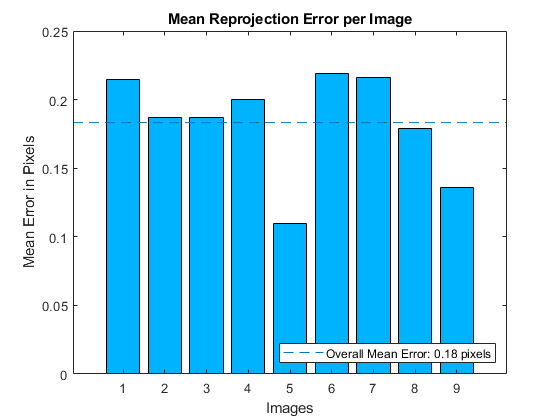

showReprojectionErrors(params);

Visualize camera extrinsics.

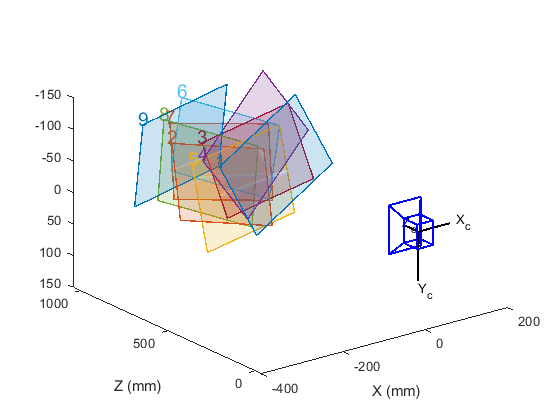

Error using zlabel (line 30)
Operation terminated by the user.

Error in showExtrinsics/labelPlotAxesCameraCentric (line 376)
        zlabel(hAxes, addUnits('Y'));

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('showExtrinsics/cameraCentric', 'C:\Program Files\MATLAB\R2020b\toolbox\vision\vision\showExtrinsics.m', 270)" style="font-weight:b

figure;
showExtrinsics(params);

drawnow;

Plot detected and reprojected points.

figure; 
imshow(imageFileNames{1}); 
hold on;
plot(imagePoints(:,1,1), imagePoints(:,2,1),'go');
plot(params.ReprojectedPoints(:,1,1),params.ReprojectedPoints(:,2,1),'r+');
legend('Detected Points','ReprojectedPoints');
hold off;

*Copyright 2012 The MathWorks, Inc.*